## Lab 2 - Alpha and Artifacts

Dua Kaurejo

**Goal**: Using the dataset provided, your goal is to identify the 10 “gestures” performed.  The gestures include two instances each of “Horizontal eye movement, vertical eye  movement, eye blinks, EMG, and closed eyes alpha activity”. 

**HEOG **(Ch 1 & 2)

- 0.1 - 5 Hz, large peaks in low frequency range in HEOG channels

**VEOG **(Ch 3 & 4)

- 0.1 - 5 Hz, large peaks in low freq range in VEOG channels

**Eye Blinks **

- under 10Hz (class notes), typically 1-4Hz, sharp, transient spikes in both HEOG & VEOG channels

**EMG (Muscle Activity)**

- broad, <30 - 300Hz (class notes), typically 20-150Hz, high frequency noise visible in multiple channels when muscle activity occurs

**Alpha Activity (Closed Eyes)**

- 8 - 13 Hz, peaks in this freq range espcially in EEG channels

- shut eye - high amplitude activity especially in O1&O2 , open - low amplitude activity

Ch 5 - EEG - O1 - left occipital lobe

Ch 6 - EEG - POz - midline

Ch 7 - EEG - O2 - right occipital lobe

**Fs = 256Hz**

*CTRL + R - comment*

clear; close all; clc;
load('lab2data.mat')
Fs = 256; % Sampling Frequency, Hz

set(0, 'DefaultAxesFontSize', 16);  % Set default font size to 12 for all axes
set(0, 'DefaultTextFontSize', 16);  % Set default font size to 12 for all text elements


## **Preprocessing**

wo = 60/(Fs/2);  % Normalized frequency (Fs is the sampling frequency)
bw = wo/35;      % Bandwidth based on a quality factor of 35
[bnf, anf] = iirnotch(wo, bw);  % Coefficients of the notch filter

% Define high pass filter >0.5Hz to remove pulse artifacts
fc = 0.5; % cutoff, Hz
order = 3; 
[bhpf, ahpf] = butter(order, fc/(Fs/2), 'high'); 

% take log(10 power) to convert to decibels instead of absolute value 

### **HEOG**

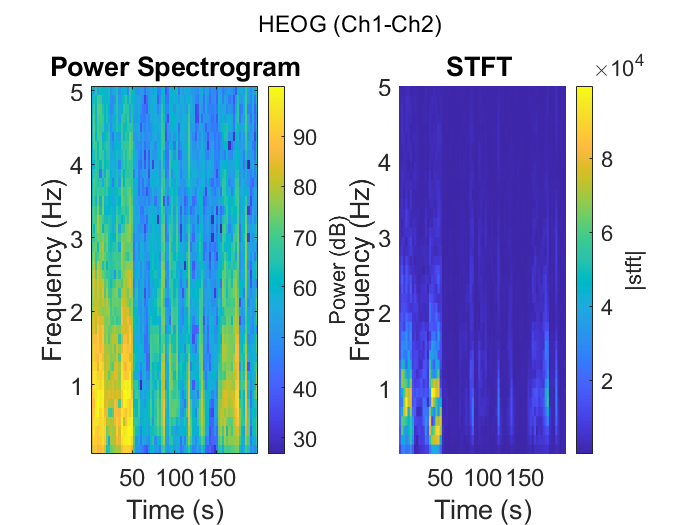

heog_raw = signal(:,1)-signal(:,2); 
L_heog=length(heog_raw);

heog_ = heog_raw - mean(heog_raw);

% Remove artifacts
heog1 = filter(bnf, anf, heog_); 
heog = filter(bhpf, ahpf, heog1); 

% figure
% plot(heog)





% Short-time Fourier Transform
window_size = round(5*Fs); % 5 second window
window = hamming(window_size);
overlap = round(0.5 * window_size); % 50% overlap
nfft = 2^nextpow2(window_size); % # of FFT points

[s, f, t] = stft(heog, Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );

fmin = .1; 
fmax = 5;
freq_range = (f>=fmin & f<=fmax);


power_stft = abs(s).^2; 
% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('HEOG (Ch1-Ch2)')


% subplot(2,1,2)
% surf(t*Fs, f(freq_range), 20*log10(abs(s(freq_range,:))), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT log10(Magnitude) of HEOG Signal');
% colorbar;
% caxis([0 100])

### **VEOG**

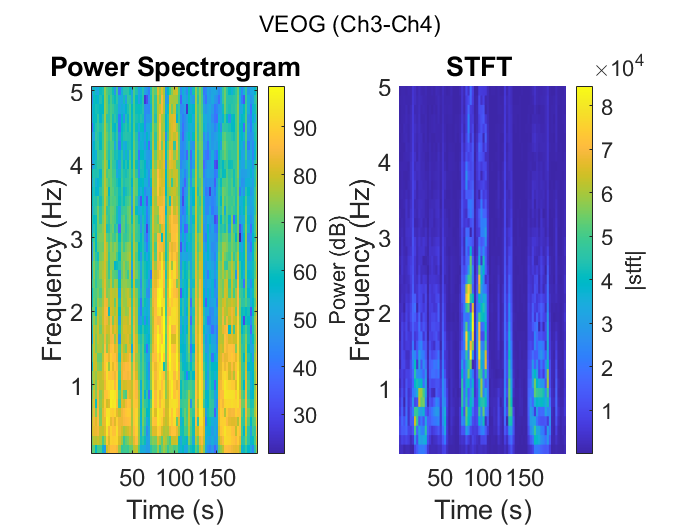

veog_raw = signal(:,3)-signal(:,4);

L_veog=length(veog_raw);

veog_ = veog_raw - mean(veog_raw);

% Remove artifacts
veog1 = filter(bnf, anf, veog_); 
veog = filter(bhpf, ahpf, veog1); 


% Short-time Fourier Transform
window_size = round(5*Fs); % 5 second window
window = hamming(window_size);
overlap = round(0.5 * window_size); % 50% overlap
nfft = 2^nextpow2(window_size); % # of FFT points

[s, f, t] = stft(veog, Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );

fmin = .1; 
fmax = 5;
freq_range = (f>=fmin & f<=fmax);


power_stft = abs(s).^2; 
% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('VEOG (Ch3-Ch4)')

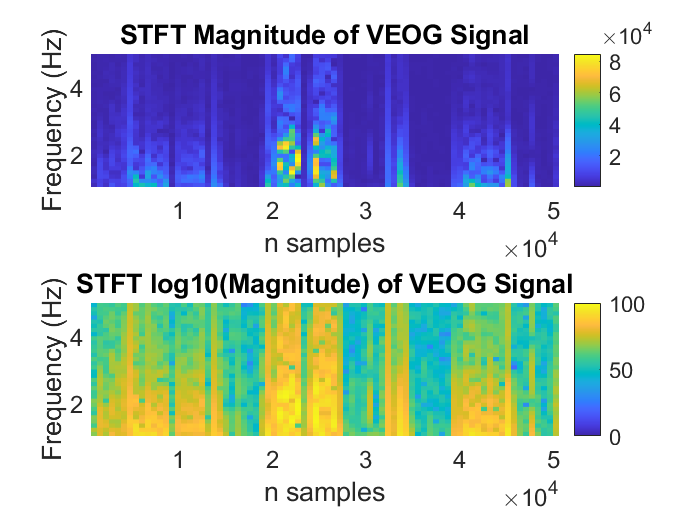









fmin = 1; 
fmax = 5;
freq_range = (f>=fmin & f<=fmax);

figure; 
subplot(2,1,1)
surf(t*Fs, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('n samples');
ylabel('Frequency (Hz)');
title('STFT Magnitude of VEOG Signal');
colorbar;

subplot(2,1,2)
surf(t*Fs, f(freq_range), 20*log10(abs(s(freq_range,:))), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('n samples');
ylabel('Frequency (Hz)');
title('STFT log10(Magnitude) of VEOG Signal');
colorbar;
caxis([0 100])

### Blinks

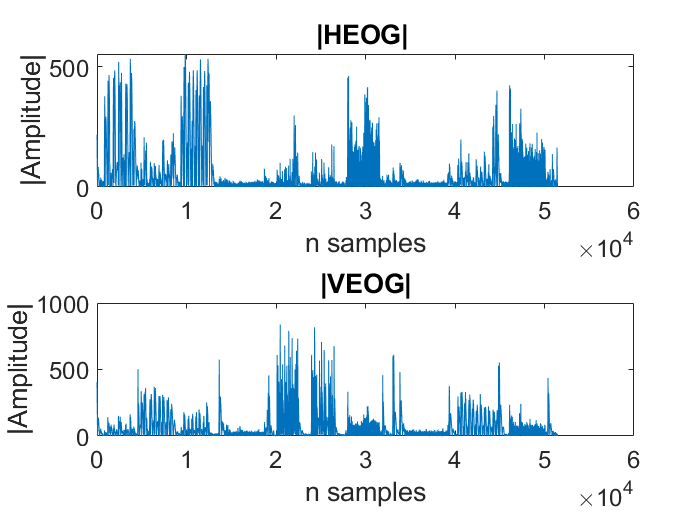

figure
subplot(2,1,1)
plot(abs(heog))
xlabel('n samples')
ylabel('|Amplitude|')
title('|HEOG| ')
subplot(2,1,2)
plot(abs(veog))
xlabel('n samples')
ylabel('|Amplitude|')
title('|VEOG|')


% 
% %heog
% 
% 
% % Short-time Fourier Transform
% window_size = round(.5*Fs); % 100ms  window
% window = hamming(window_size);
% overlap = round(0.5 * window_size); % 50% overlap
% nfft = 2^nextpow2(window_size); % # of FFT points
% 
% [s, f, t] = stft(heog, Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );
% 
% 
% fmin = .5; 
% fmax = 4;
% freq_range = (f>=fmin & f<=fmax);
% 
% figure; 
% subplot(2,1,1)
% surf(t*Fs, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of HEOG Signal');
% colorbar;

% % VEOG
% 
% 
% [s, f, t] = stft(veog, Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );
% freq_range = (f>=fmin & f<=fmax);
% 
% figure; 
% subplot(2,1,1)
% surf(t*Fs, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of VEOG Signal');
% colorbar;
% 
% subplot(2,1,2)
% surf(t*Fs, f(freq_range), 20*log10(abs(s(freq_range,:))), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT log10(Magnitude) of VEOG Signal');
% colorbar;
% caxis([0 100])












### EMG 

- broad, <30 - 300Hz (class notes), typically 20-150Hz, high frequency noise visible in multiple channels when muscle activity occurs

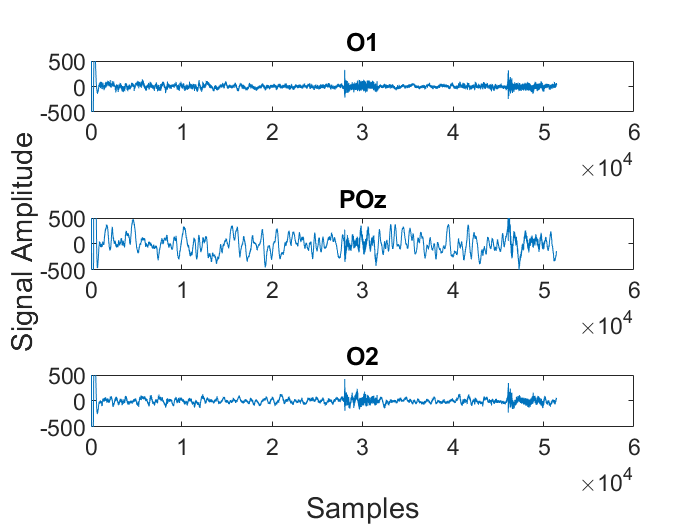

eeg_raw = [signal(:,5), signal(:,6), signal(:,7)];
L_eeg=length(eeg_raw);


% Remove artifacts
eeg1 = filter(bnf, anf, eeg_raw); 
eegF = filter(bhpf, ahpf, eeg1); 
mean_cols = mean(eegF, 1);
eeg = eegF - mean_cols; 

figure;
subplot(3,1,1)
plot(eeg(:,1))
title('O1')
ylim([-500 500])
subplot(3,1,2)
plot(eeg(:,2))
title('POz')
ylim([-500 500])
subplot(3,1,3)
plot(eeg(:,3))
title('O2')
ylim([-500 500])
% Add a single xlabel and ylabel for the entire figure
% Position the labels manually for better alignment
han = axes(gcf, 'visible', 'off');  % Create an invisible axes
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';

% Set the xlabel and ylabel for the entire figure
ylabel(han, 'Signal Amplitude');
xlabel(han, 'Samples');

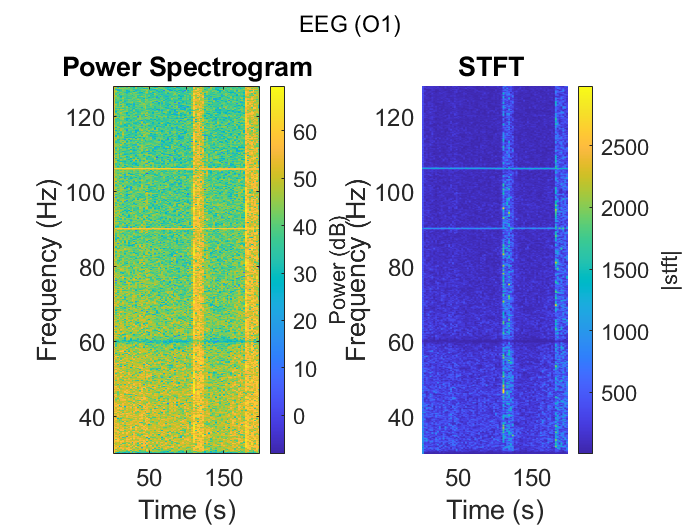






% Short-time Fourier Transform
window_size = round(5*Fs); % 5 second window
window = hamming(window_size);
overlap = round(0.5 * window_size); % 50% overlap
nfft = 2^nextpow2(window_size); % # of FFT points

% O1

[s, f, t] = stft(eeg(:,1), Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );
so1 = s; fo1 = f; to1 = t; 

fmin = 30; 
fmax = 300;
freq_range = (f>=fmin & f<=fmax);

power_stft = abs(s).^2; 
% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('EEG (O1)')

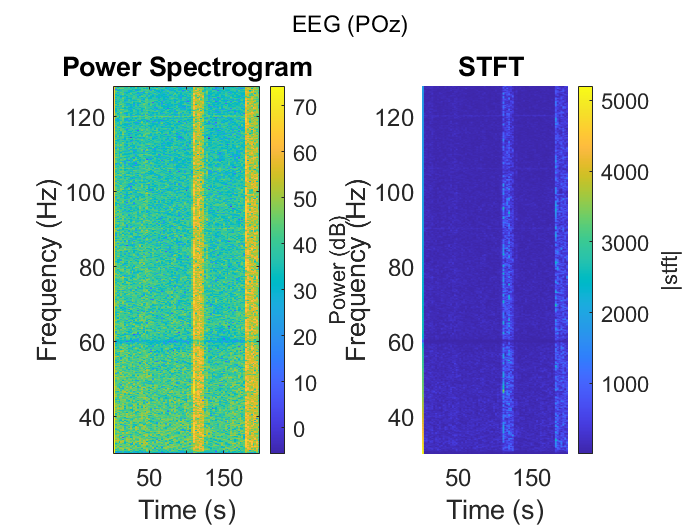








% figure; 
% surf(t*Fs, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of EEG - O1 Signal');
% colorbar;

% POz
[s, f, t] = stft(eeg(:,2), Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );
spoz = s; fpoz = f; tpoz = t; 

freq_range = (f>=fmin & f<=fmax);

power_stft = abs(s).^2; 
% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('EEG (POz)')

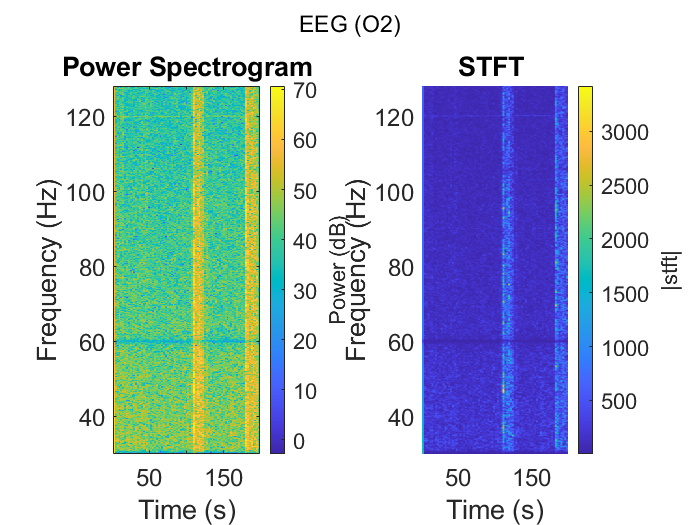





% figure; 
% surf(t*Fs, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of EEG - POz Signal');
% colorbar;

%O2
[s, f, t] = stft(eeg(:,3), Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );
so2 = s; fo2 = f; to2 = t; 

fmin = 30; 
fmax = 300;
freq_range = (f>=fmin & f<=fmax);

power_stft = abs(s).^2; 
% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('EEG (O2)')



% figure; 
% surf(t*Fs, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of EEG - O2 Signal');
% colorbar;

**Alpha Activity (Closed Eyes)**

Ch 5 - EEG - O1 - left occipital lobe

Ch 6 - EEG - POz - midline

Ch 7 - EEG - O2 - right occipital lobe

- 8 - 13 Hz, peaks in this freq range espcially in EEG channels

- shut eye - high amplitude activity especially in O1&O2 , open - low amplitude activity

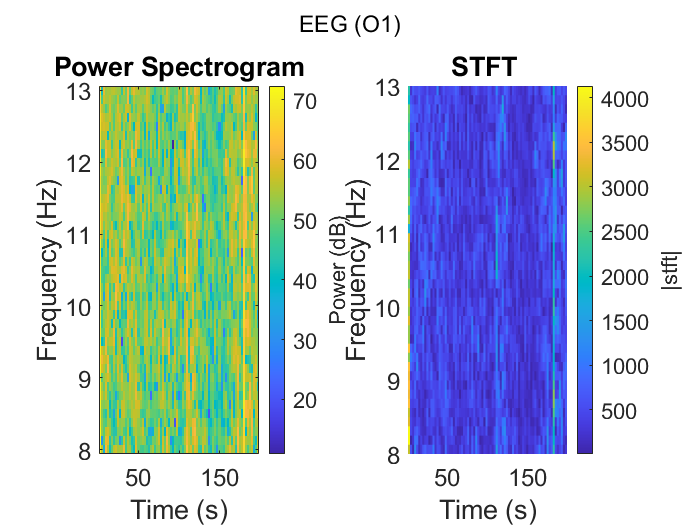

%so1 = s; fo1 = f; to1 = t; 
% Short-time Fourier Transform
window_size = round(5*Fs); % 5 second window
window = hamming(window_size);
overlap = round(0.5 * window_size); % 50% overlap
nfft = 2^nextpow2(window_size); % # of FFT points

% O1
[s, f, t] = stft(eeg(:,1), Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );

fmin = 8; 
fmax = 13;
freq_range = (f>=fmin & f<=fmax);

power_stft = abs(s).^2; 

% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('EEG (O1)')

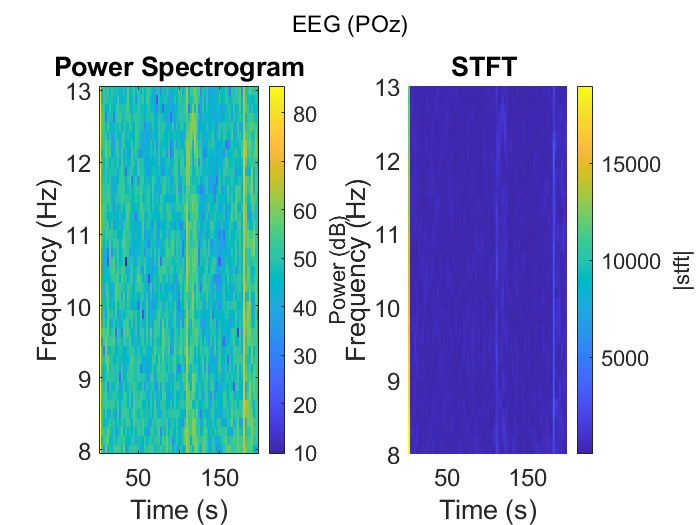




% figure; 
% surf(to1*Fs, fo1(freq_range), abs(so1(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of EEG - O1 Signal');
% colorbar;

% POz


[s, f, t] = stft(eeg(:,2), Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );

freq_range = (f>=fmin & f<=fmax);
power_stft = abs(s).^2; 

% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('EEG (POz)')

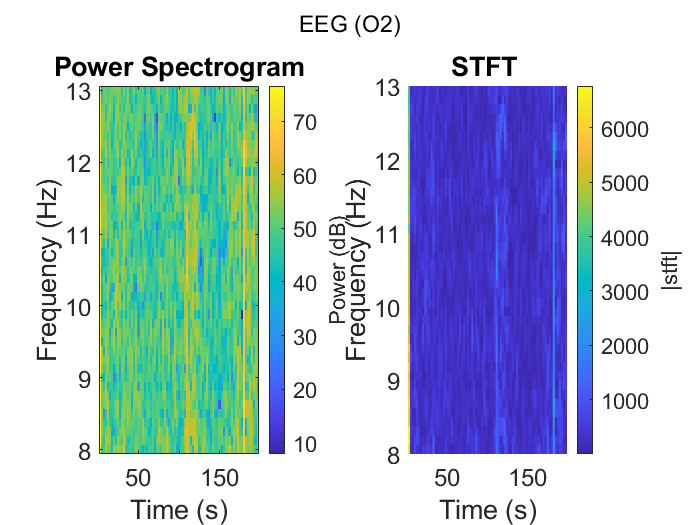












% figure; 
% surf(to1*Fs, fo1(freq_range), abs(so1(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of EEG2 Signal');
% colorbar;


% O2 

[s, f, t] = stft(eeg(:,3), Fs, 'Window', window, 'OverlapLength', overlap,'FFTLength', nfft );

freq_range = (f>=fmin & f<=fmax);
power_stft = abs(s).^2; 

% Visualize the power spectrogram
figure; 
subplot(1,2,1)
imagesc(t, f(freq_range), 10*log10(power_stft(freq_range,:)));  % Convert power to dB for better visualization
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power Spectrogram');
c=colorbar;
ylabel(c, 'Power (dB)')

subplot(1,2,2)
surf(t, f(freq_range), abs(s(freq_range,:)), 'EdgeColor', 'none');
axis tight;
view(0, 90); % Top-down view
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT ');
c=colorbar;
ylabel(c, '|stft|')
sgtitle('EEG (O2)')








% figure; 
% surf(to1*Fs, fo1(freq_range), abs(so1(freq_range,:)), 'EdgeColor', 'none');
% axis tight;
% view(0, 90); % Top-down view
% xlabel('n samples');
% ylabel('Frequency (Hz)');
% title('STFT Magnitude of EEG - O1 Signal');
% colorbar;